clear all;
close all;
clc;

addpath("ExtrinsicCalibration");
addpath("funzioni");
run("estraz_dati_calib_new.m");

Sincronizzazione completata sul tempo degli Encoders. Righe finali: 14072


T_synced = 14072×9 table
    Tempo [s]    X_HTC [m]    Y_HTC [m]    Z_HTC [m]    DegX_HTC [deg]    DegY_HTC [deg]    DegZ_HTC [deg]    Left_ENC [tic]    Right_ENC [tic]
    _________    _________    _________    _________    ______________    ______________    ______________    ______________    _______________

          0       2.9559       -2.4895     -0.79251         0.8635           -1.5229            83.011              0                 -1       
      0.011       2.9559       -2.4896     -0.79248        0.86084           -1.5245             83.01              0                 -1       
      0.021       2.9558       -2.4896     -0.79246        0.85907           -1.5257        

## Encoders Data

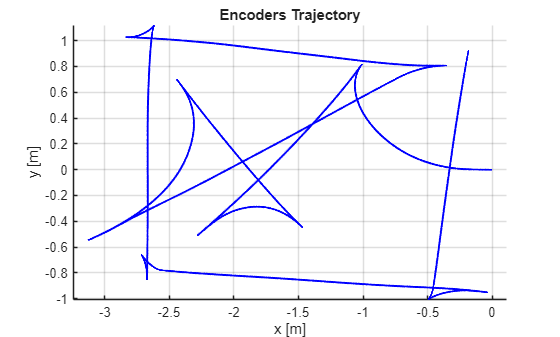

MOTION_START = 1;

b_= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;

K_param = [b_, Rr, Rl];

Ntic_R = table2array(T_synced(1:end,"Right_ENC [tic]"));
Ntic_L = table2array(T_synced(1:end,"Left_ENC [tic]"));

%Tic incremento at each step steps
Ntic_R = diff(Ntic_R);
Ntic_L = diff(Ntic_L);

% pose_Enc_formulas = [x(t) y(t) theta(t)]
pose_Enc_formulas = EncodersMotion(K_param, Ntic_L, Ntic_R, Enc_res);

x_ENC = pose_Enc_formulas(1,:);
y_ENC = pose_Enc_formulas(2,:);
theta_ENC = pose_Enc_formulas(3,:);

figure(4); clf; hold on; grid on;
plot(x_ENC, y_ENC, 'LineWidth', 1.5, "Color", "b");

xlabel('x [m]');
ylabel('y [m]');
title('Encoders Trajectory');
axis("equal");

## HTC Raw Data

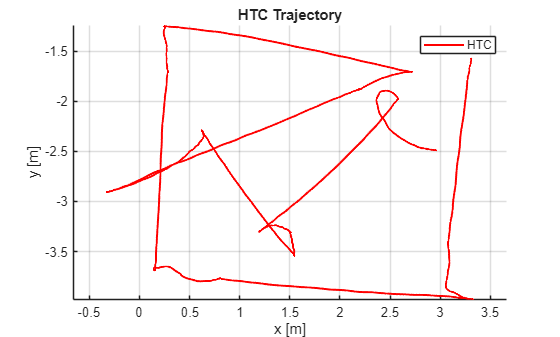

%% HTC Data
x_HTC = table2array(T_synced(MOTION_START:end-1, "X_HTC [m]"));
y_HTC = table2array(T_synced(MOTION_START:end-1, "Y_HTC [m]"));

% x_HTC = x_HTC - x_HTC(1);
% y_HTC = y_HTC - y_HTC(1);

theta_HTC = table2array(T_synced(MOTION_START:end-1, "DegZ_HTC [deg]")); %deg around Z
theta_HTC = unwrap(theta_HTC); %to solve phase problems
theta_HTC = deg2rad(theta_HTC); %rad

figure(2); clf; hold on; grid on;
plot(x_HTC, y_HTC, 'LineWidth', 1.5, "Color", "r");
xlabel('x [m]');
ylabel('y [m]');
title('HTC Trajectory');
legend('HTC');
axis("equal");

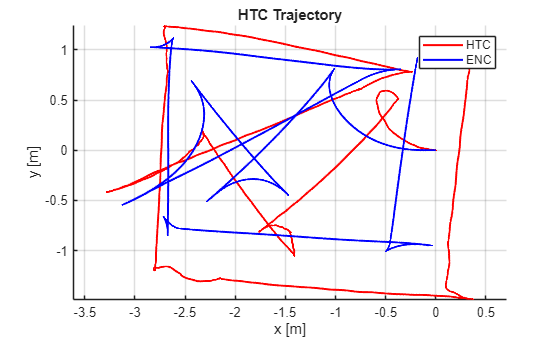

figure; clf; hold on; grid on;
plot(x_HTC - x_HTC(1), y_HTC - y_HTC(1), 'LineWidth', 1.5, "Color", "r");
plot(x_ENC, y_ENC, 'LineWidth', 1.5, "Color", "b");
xlabel('x [m]');
ylabel('y [m]');
title('HTC Trajectory');
legend('HTC', 'ENC');
axis("equal");

## Calibration from Simultaneous Calibration of Odometry and Sensor Parameters for Mobile Robots Censi et. al.

All the following procedure il taken form  "Simultaneous Calibration of Odometry and Sensor Parameters for Mobile Robots Censi et. al." ([Web Link](https://www.researchgate.net/publication/260634803_Simultaneous_Calibration_of_Odometry_and_Sensor_Parameters_for_Mobile_Robots)). 

The algorithm performed is the following:

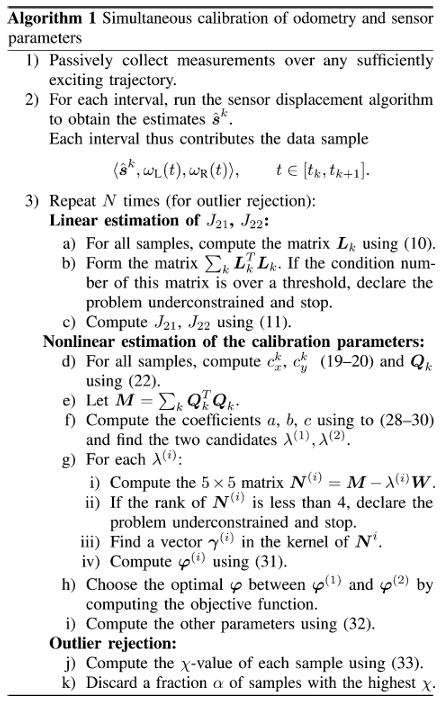

More details in the paper. 

Now follows the code that implements all the steps shown above:

%% === STEP 3 === %%
% == Step 3a == %
L = [(2*pi/Enc_res)*Ntic_L (2*pi/Enc_res)*Ntic_R];

% Covariance of the measurement estimate (arbitrarily chosen)
sigma_theta_sqrd = 0.1; 
sigma_xy_sqrd = 0.1; 

Sigma = [sigma_xy_sqrd        0               0;
                  0       sigma_xy_sqrd         0;
                  0             0        sigma_theta_sqrd];

Matrix_Sum = (L' * L) / sigma_theta_sqrd;

% == Step 3b and 3c == %
% Computation of the therms s_k
dx_global = [0; diff(x_HTC)];
dy_global = [0; diff(y_HTC)];

% Rimozione offset iniziale
initial_offset = theta_HTC(1); 
th_global = theta_HTC - initial_offset;

s_x = zeros(size(dx_global));
s_y = zeros(size(dy_global));

% Devo ruotare i vari sk perchè rappresentano la trasformazione dal frame
% locale dall'istante k al frame locale all'istante k+1 ma i dati che ho a
% disposizione sono globali 
for k = 2:length(dx_global)
    % Uso l'angolo al passo precedente k-1 per proiettare il movimento
    th = th_global(k-1); 
    
    R = [cos(th), sin(th); 
        -sin(th), cos(th)];
    
    % Proiezione del delta globale nel frame locale
    delta_local = R * [dx_global(k); dy_global(k)];
    
    s_x(k) = delta_local(1); 
    s_y(k) = delta_local(2);
end

s_theta = [0; diff(theta_HTC)];

Vector_Sum = (L' * s_theta) / sigma_theta_sqrd;


% Computation of J21 and J22
J = Matrix_Sum \ Vector_Sum;
J21 = J(1)

J21 = -0.0985

J22 = J(2)

J22 = 0.0981



% == Step 3d == %
Time = table2array(T_synced(MOTION_START:end-1, "Tempo [s]"));
dt = Time(2) - Time(1);

omega_L = (2*pi*Ntic_L) /(Enc_res*dt)';
omega_R = (2*pi*Ntic_R) /(Enc_res*dt)';

r_theta = [0 diff(theta_ENC)]';

% cx and cy therms
cx = 0.5 * (-J21 * omega_L + J22 * omega_R) .* cos(r_theta) * dt;
cy = 0.5 * (-J21 * omega_L + J22 * omega_R) .* sin(r_theta) * dt;

% Matrix Q
Q{length(Ntic_R)} = zeros(2,5);
for k = 1:length(Ntic_R)
    Q{k} = (1/sqrt(sigma_xy_sqrd)) * [  -cx(k)     1-cos( r_theta(k) )     sin( r_theta(k) )     s_x(k)     -s_y(k);
                                        -cy(k)     -sin( r_theta(k) )     1-cos( r_theta(k) )    s_y(k)      s_x(k)];
end

% == Step 3e == %
M = zeros(5, 5); 
for k = 1:length(Ntic_R)
    M = M + Q{k}' * Q{k};
end

M

M =     1.7523   -0.0007   -0.2469   -1.3820   -0.3348
   -0.0007    0.6816         0    0.1402    0.0099
   -0.2469         0    0.6816   -0.0099    0.1402
   -1.3820    0.1402   -0.0099    1.3190         0
   -0.3348    0.0099    0.1402         0    1.3190


% == Step 3f == %
a2 = M(1,1)*M(2,2)^2 - M(2,2)*M(1,3)^2

a2 = 0.7726


a1 = 2*M(1,3)*M(2,2)*M(3,5)*M(1,5) ...
     - M(2,2)^2*M(1,5)^2 ...
     + 2*M(1,3)*M(2,2)*M(3,4)*M(1,4) ...
     - 2*M(2,2)*M(1,3)^2*M(4,4) ...
     - M(2,2)^2*M(1,4)^2 ...
     + 2*M(1,1)*M(2,2)^2*M(4,4) ...
     + M(1,3)^2*M(3,5)^2 ...
     - 2*M(1,1)*M(2,2)*M(3,4)^2 ...
     + M(1,3)^2*M(3,4)^2 ...
     - 2*M(1,1)*M(2,2)*M(3,5)^2

a1 = 1.0638


a0 = -2*M(1,3)*M(3,5)^3*M(1,5) ...
     - M(2,2)*M(1,3)^2*M(4,4)^2 ...
     + M(1,3)^2*M(3,5)^2*M(4,4) ...
     + 2*M(1,3)*M(2,2)*M(3,4)*M(1,4)*M(4,4) ...
     + 2*M(1,3)*M(2,2)*M(3,5)*M(1,5)*M(4,4) ...
     + M(1,3)^2*M(3,4)^2*M(4,4) ...
     - 2*M(1,1)*M(2,2)*M(3,4)^2*M(4,4) ...
     - 2*M(1,3)*M(3,4)^3*M(1,4) ...
     - 2*M(1,1)*M(2,2)*M(3,5)^2*M(4,4) ...
     + 2*M(1,1)*M(3,5)^2*M(3,4)^2 ...
     + M(2,2)*M(1,4)^2*M(3,5)^2 ...
     - 2*M(1,3)*M(3,5)^2*M(3,4)*M(1,4) ...
     - 2*M(1,3)*M(3,4)^2*M(3,5)*M(1,5) ...
     + M(1,1)*M(3,4)^4 ...
     + M(2,2)*M(1,5)^2*M(3,4)^2 ...
     + M(2,2)*M(3,5)^2*M(1,5)^2 ...
     + M(1,1)*M(3,5)^4 ...
     + M(1,1)*M(2,2)^2*M(4,4)^2 ...
     + M(2,2)*M(3,4)^2*M(1,4)^2 ...
     - M(2,2)^2*M(1,5)^2*M(4,4) ...
     - M(2,2)^2*M(1,4)^2*M(4,4)

a0 = 0.0867

% Finding the two roots 
lambda = roots([a2, a1, a0])

lambda =    -1.2900
   -0.0870


% == Step 3g == %
% == Step 3g-i == %
W = [ zeros(3,3)   zeros(3,2);
      zeros(2,3)   eye(2,2)  ];

N1 = M + lambda(1)*W;
N2 = M + lambda(2)*W;

% == Step 3g-iii == %
% Finding a vector in the kernel of N1
% Uso l'autovettore assoclait oall'autovalore più piccolo
[V1, D1] = eig(N1);
diag_D1 = diag(D1);               
[~, idx1] = min(abs(diag_D1));    
gamma1 = V1(:, idx1)

gamma1 =    -0.0000
    0.0266
   -0.2002
   -0.1967
    0.9595


% Finding a vector in the kernel of N1
% Uso l'autovettore assoclait oall'autovalore più piccolo
[V2, D2] = eig(N2);
diag_D2 = diag(D2);
[~, idx2] = min(abs(diag_D2));   
gamma2 = V2(:, idx2)

gamma2 =    -0.6264
    0.1499
   -0.2070
   -0.7214
   -0.1479


% == Step 3g-iv == %
phi1 = ( sign(gamma1(1))/norm( [gamma1(4) gamma1(5)]' ) ) * gamma1

phi1 =     0.0000
   -0.0271
    0.2044
    0.2008
   -0.9796


phi2 = ( sign(gamma2(1))/norm( [gamma2(4) gamma2(5)]' ) ) * gamma2

phi2 =     0.8506
   -0.2035
    0.2811
    0.9796
    0.2008


ccording to Step 3h of the algorithm, we must select between the two candidate solutions, phi1 and phi2. The correct solution is evidently phi2, as its first component phi2(1) represents a physically plausible baseline b.

We now proceed by extracting all quantities of interest from phi_2:

% == Ster 3i %
b = phi2(1)

b = 0.8506

rl = -phi2(1)*J21

rl = 0.0838

rr =  phi2(1)*J22

rr = 0.0835

l = [phi2(2)  phi2(3)  atan2(phi2(5), phi2(4))] % [l_x, l_y, l_theta]

l =    -0.2035    0.2811    0.2022


## Plots

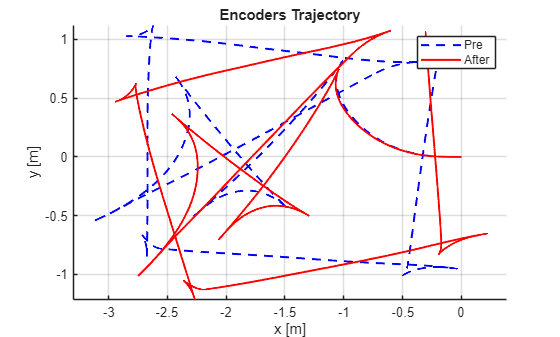

% pose_Enc_formulas = [x(t) y(t) theta(t)]
K_param_new = [b, rr, rl];
pose_Enc_formulas_new = EncodersMotion(K_param_new, Ntic_L, Ntic_R, Enc_res);

x_ENC_new = pose_Enc_formulas_new(1,:);
y_ENC_new = pose_Enc_formulas_new(2,:);
theta_ENC_new = pose_Enc_formulas_new(3,:);

figure; clf; hold on; grid on;
plot(x_ENC, y_ENC, 'LineWidth', 1.5, "Color", "b", "LineStyle", "--");
plot(x_ENC_new, y_ENC_new, 'LineWidth', 1.5, "Color", "r");
xlabel('x [m]');
ylabel('y [m]');
legend('Pre', 'After');
title('Encoders Trajectory');
axis("equal");

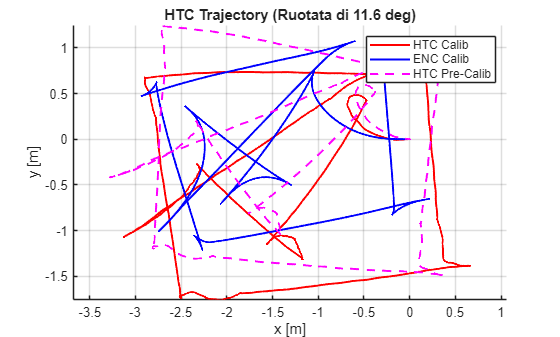

% 1. Definizione dell'angolo di rotazione
theta_rot = l(3); % Angolo in radianti

% 2. Creazione della Matrice di Rotazione (2D)
R_matrix = [cos(theta_rot), -sin(theta_rot);
            sin(theta_rot),  cos(theta_rot)];

% 3. Preparazione dei dati (Vettori colonna -> Matrice 2xN)
% Assumiamo che x_HTC e y_HTC siano vettori colonna.
% Li trasponiamo se necessario per avere [x; y]
Points = [x_HTC, y_HTC]'; 

% 4. Applicazione della rotazione
Points_rotated = R_matrix * Points;

% 5. Estrazione delle nuove coordinate ruotate
x_rot = Points_rotated(1, :)';
y_rot = Points_rotated(2, :)';

% 6. Plotting
figure; clf; hold on; grid on;

% Plot originale (opzionale, per confronto - in grigio chiaro)
% plot(x_HTC, y_HTC, 'LineWidth', 1, "Color", [0.8 0.8 0.8], 'DisplayName', 'Originale');

% Plot ruotato (in rosso come richiesto)
plot(x_rot - x_rot(1), y_rot - y_rot(1), 'LineWidth', 1.5, "Color", "r");
plot(x_ENC_new, y_ENC_new, 'LineWidth', 1.5, "Color", "b");
plot(x_HTC - x_HTC(1), y_HTC - y_HTC(1), 'LineWidth', 1.5, "Color", "m", "LineStyle", "--");
xlabel('x [m]');
ylabel('y [m]');
title(['HTC Trajectory (Ruotata di ' num2str(rad2deg(theta_rot), '%.1f') ' deg)']);
legend('HTC Calib', 'ENC Calib', 'HTC Pre-Calib');
axis("equal");